### Ejercicio 1

Identificar si los siguientes son nombres válidos de variables 

- _altura 

- altura_

- 2paises

- Musica_Favorita

- Numero-de-pacientes 

### Solucion

% Ingrese su código aqui 
isvarname _altura 

ans = logical
   0


isvarname altura 

ans = logical
   1


isvarname 2paises

ans = logical
   0


isvarname Musica_Favorita

ans = logical
   1


isvarname Numero-de-pacientes 

ans = logical
   0


### Ejercicio 2

Realizar las siguientes operaciones 

- 
$$\pi^{e+1}$$


- 
$$\sqrt{\sqrt[3\ldotp 71]{\frac{e^{\pi } }{2}}}$$


- 
$$\frac{\sqrt{5a+{3b}^{2a} }}{\sqrt[a]{3\ldotp 1b}}$$


### Solucion

% primera solución
x= 2.1;
3.14^(x+1)

ans = 34.7122

% segunda solución 
((exp(pi)/2)^(1/3.71))^(1/2)

ans = 1.3909

% tercera solución
a=pi;
b=0.5;
((5*a+3*b^(2*a))^(1/2))/(3.1*b)^a

ans = 1.0015

### Ejercicio 3

1. El área de un circulo se encuentra mediante la expresión $A=\pi r^2$. Considerando lo anterior:

- Determinar el radio que tiene un circulo de área $2\pi u^2$

- Cuál es la diferencia entre el anterior radio y el radio de un circulo de área $5\ldotp 2\pi u^2$?

- Cuál debe ser el radio para que el área sea $\pi {*10}^2 u^2$?

2. Luego, el volumen de un cilindro se determina medante el area de la base y la altura, $V=A_{\textrm{base}} *h=\pi r^2 h$, Entonces:

- Cuál debe ser el área para que el volumen de un cilindro sea de $10u^3 \textrm{con}\;\textrm{una}\;\textrm{altura}\;\textrm{de}\;2\ldotp 5u?$

- Cuáles serán las alturas para volúmenes desde $1u^3 \;\textrm{hasta}\;1000u^3$con un diametro de 10u?

- Utilizando las alturas anteriores, Cuál debe ser el área para que el volumen sea $500u^3$ en todos los casos ?

% literal 1
clear
r=2*pi;
A1=pi*r^2

A1 = 124.0251


% literal 2
r=5.2*pi;
A2=pi*r^2

A2 = 838.4097

deltaA= A2-A1

deltaA = 714.3846


% literal 3 
A3= pi*10^2;
r=sqrt(A3/pi)

r = 10

% literal 4
V= 10;
h=2.5;
AC= V/h

AC = 4


%literal 5 
V=1:1000;
d=10;
h=V/((pi*d^2))/4

h =     0.0008    0.0016    0.0024    0.0032    0.0040    0.0048    0.0056    0.0064    0.0072    0.0080    0.0088    0.0095    0.0103    0.0111    0.0119    0.0127    0.0135    0.0143    0.0151    0.0159    0.0167    0.0175    0.0183    0.0191    0.0199    0.0207    0.0215    0.0223    0.0231    0.0239    0.0247    0.0255    0.0263    0.0271    0.0279    0.0286    0.0294    0.0302    0.0310    0.0318    0.0326    0.0334    0.0342    0.0350    0.0358    0.0366    0.0374    0.0382    0.0390    0.0398


%  literal 6
V=500;
A= V./h

A = 	1.0e+05 *

    6.2832    3.1416    2.0944    1.5708    1.2566    1.0472    0.8976    0.7854    0.6981    0.6283    0.5712    0.5236    0.4833    0.4488    0.4189    0.3927    0.3696    0.3491    0.3307    0.3142    0.2992    0.2856    0.2732    0.2618    0.2513    0.2417    0.2327    0.2244    0.2167    0.2094    0.2027    0.1963    0.1904    0.1848    0.1795    0.1745    0.1698    0.1653    0.1611    0.1571    0.1532    0.1496    0.1461    0.1428    0.1396    0.1366    0.1337    0.1309    0.1282    0.1257


**Ejercicio 5**

La ley del enfriamiento de Newton establece que la tasa de pérdida de calor de un cuerpo es proporcional a la diferencia de temperatura entre el cuerpo y sus alrededores. Esta se modela mediante la siguiente ecuación

diferencial:

                                                                            
$$\frac{d}{\mathrm{dt}}P=\mathrm{kP}$$


donde:

T = temperatura actual (en Kelvin)

TA =temperatura ambiente (en Kelvin)

c = constante de proporcionalidad

t = tiempo (en segundos)

Si la temperatura de un pastel recién sacado del horno es 180° C y la temperatura ambiente es de 23.5°C ,

¿cuál será la temperatura dentro de 2 horas?

Desplegar una conclusión adecuada utilizando la función de despliegue formateado.

**Solución**  

### Ejercicio 4

Las poblaciones tienden a expandirse exponencialmente. Esto se puede modelar mediante la ecuación diferencia:

                                                                                
$$\frac{d}{\mathrm{dt}}P=\mathrm{kP}$$


donde:

P=población actual

k=tasa de crecimiento (se expresa en términos de la unidad) 

t= tiempo 

Si inicialmente se tienen 500 personas (P(0)=500) que se reproducen a una tasa de crecimiento constante de 65% por año, determinar cuántas personas habrán dentro de 4 años. Desplegar una conclusión adecuada utilizando la función de despliegue formateado.

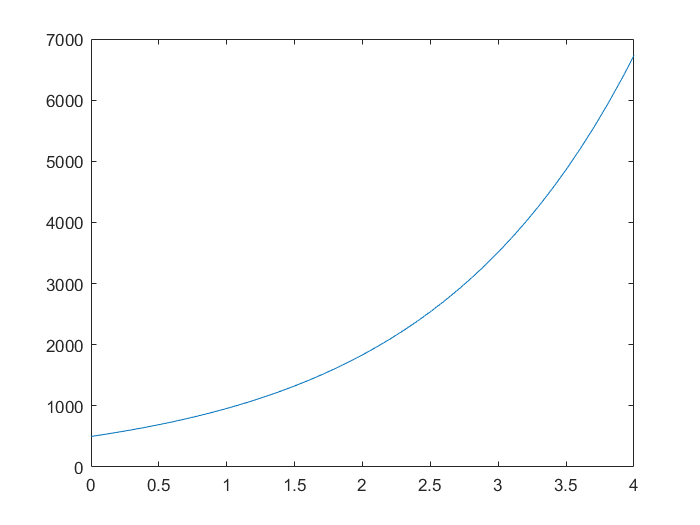

clear
tRange = [0 4];
P0 = 500;

[tSol, PSol] = ode45(@modeloPoblacional, tRange, P0);
plot(tSol,PSol)

P10=PSol(tSol==4);
fprintf("Con una poblacion inicial de %i personas, con una tasa de crecimiento de %.1f\n"+...
    "y dentro de %i años se téndra una población de %.0f personas. \n ",...
    P0, 0.65, 4, P10)

Con una poblacion inicial de 500 personas, con una tasa de crecimiento de 0.7
y dentro de 4 años se téndra una población de 6732 personas. 
 

function dPdt = modeloPoblacional(~, P)
    k = 0.65;
    dPdt = k.*P;
   
end